# OGLO notebook 7

HNXJ@github

Spectrolamniar V2.0

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
addpath(genpath('flipv2'));
generateCore();

addpath('fieldtrip');ft_defaults;
nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


nwbFile = nwbPath + nwbFiles{6};
nwb = nwbRead(nwbFile);
disp(nwbFile);

data\sub-C31o_ses-230830.nwb


[pinfo, xa] = jNWBSignals(nwb, 0, "flash", 1000, 1000, "lfp");


>flash:
->Total correct trials: 100

-->Total blocks: 1

-->Total conditions: 1

--->Condition 1 : 100 trials, 100 correct 

->Total trials: 100

Area(s): PFC
_


[pinfo, xb] = jNWBSignals(nwb, 1, "flash", 1000, 1000, "lfp");


>flash:
->Total correct trials: 100

-->Total blocks: 1

-->Total conditions: 1

--->Condition 1 : 100 trials, 100 correct 

->Total trials: 100

Area(s): V4, MT
_


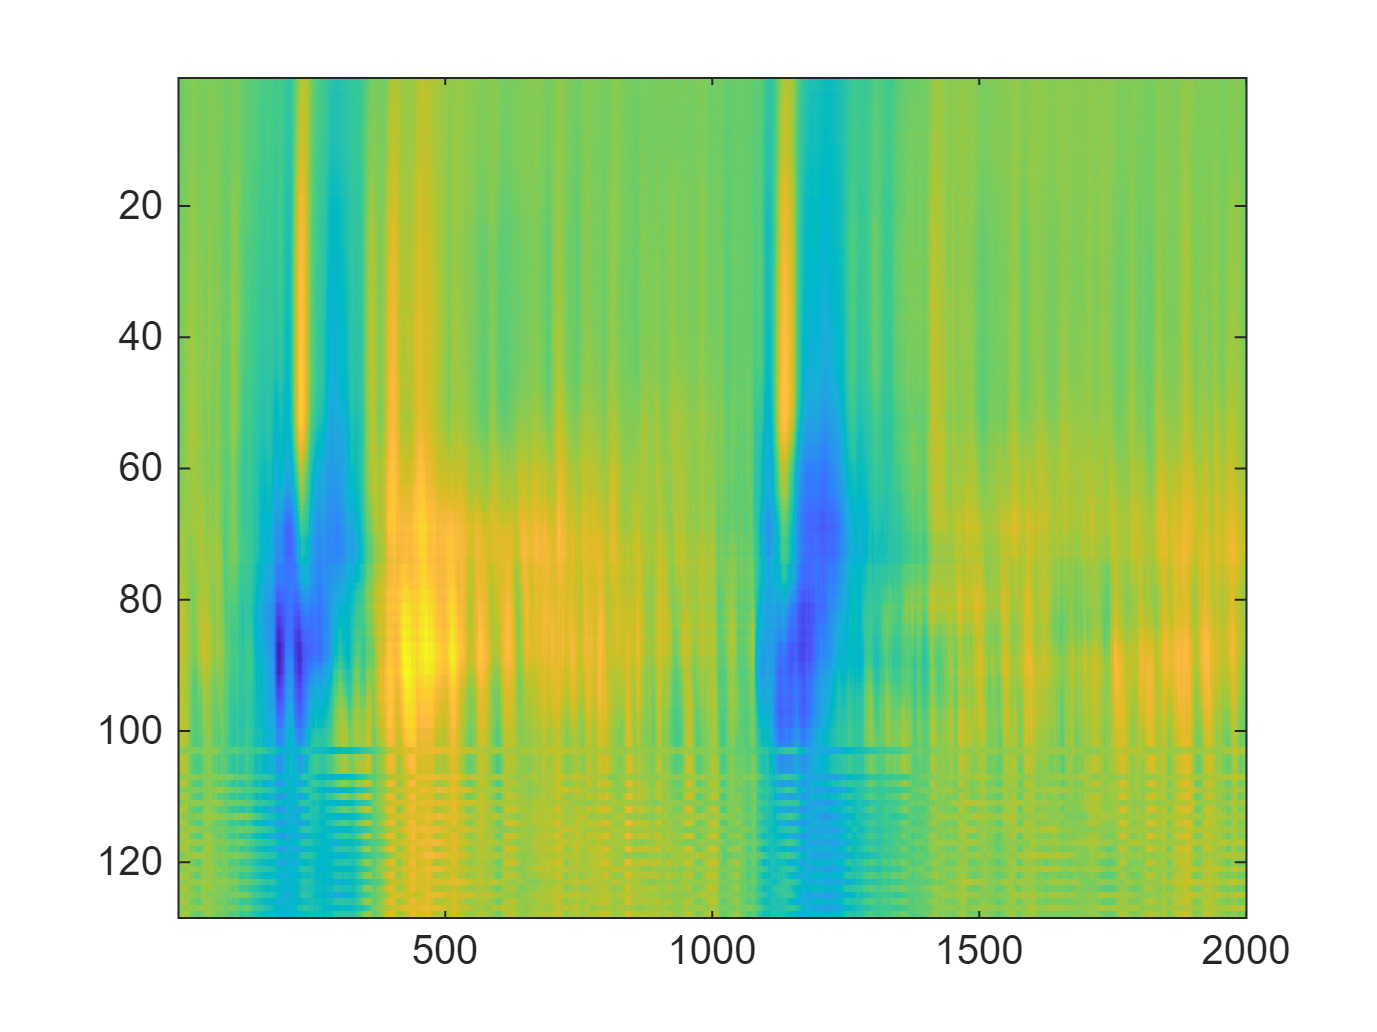

data = xa{1};
data = permute(data, [2, 3, 1]);
imx1 = squeeze(mean(data, 3));
figure;imagesc(imx1);

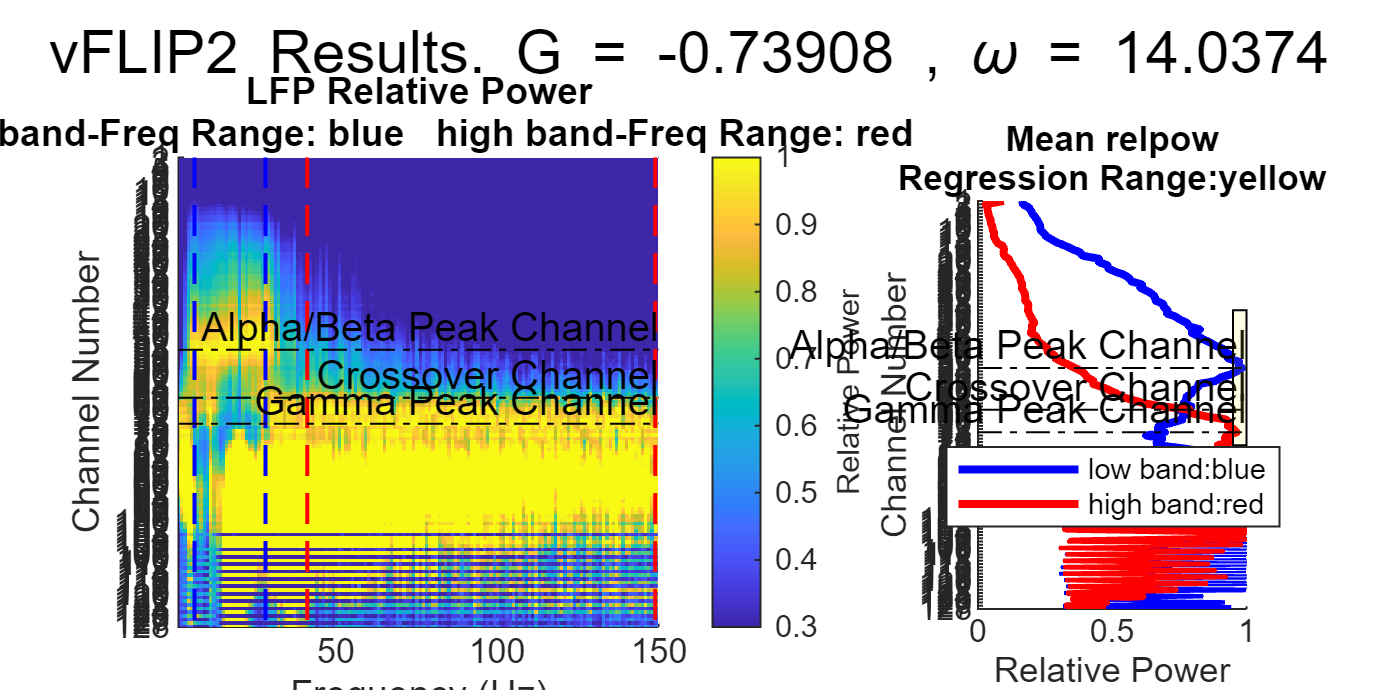

flipObj = vFLIP2(data, 'DataType', 'raw_cut', 'fsample', 1000, 'intdist', 0.1, 'plot_result', true);

results = flipObj.Results;